%% Task 1: Import and Visualize the Data
importReports

reports = 480×5 table
                                 Description                                      Category         Urgency        Resolution        Cost 
    _____________________________________________________________________    __________________    _______    __________________    _____

    "Items are occasionally getting stuck in the scanner spools."            Mechanical Failure    Medium     Readjust Machine         45
    "Loud rattling and banging sounds are coming from assembler pistons."    Mechanical Failure    Medium     Readjust Machine         35
    "There are cuts to the power when starting the plant."                   Electronic Failure    High       Full Replacement      16200
    "Fried capacitors in the assembler."                                     Electronic Failure    High       Replace


%% Preview the table
head(reports)

                                 Description                                      Category         Urgency        Resolution        Cost 
    _____________________________________________________________________    __________________    _______    __________________    _____

    "Items are occasionally getting stuck in the scanner spools."            Mechanical Failure    Medium     Readjust Machine         45
    "Loud rattling and banging sounds are coming from assembler pistons."    Mechanical Failure    Medium     Readjust Machine         35
    "There are cuts to the power when starting the plant."                   Electronic Failure    High       Full Replacement      16200
    "Fried capacitors in the assembler."                                     Electronic Failure    High       Replace Components      352
 

summary(reports)


reports: 480×5 table

Variables:

    Description: string
    Category: categorical (4 categories)
    Urgency: categorical (4 categories)
    Resolution: categorical (

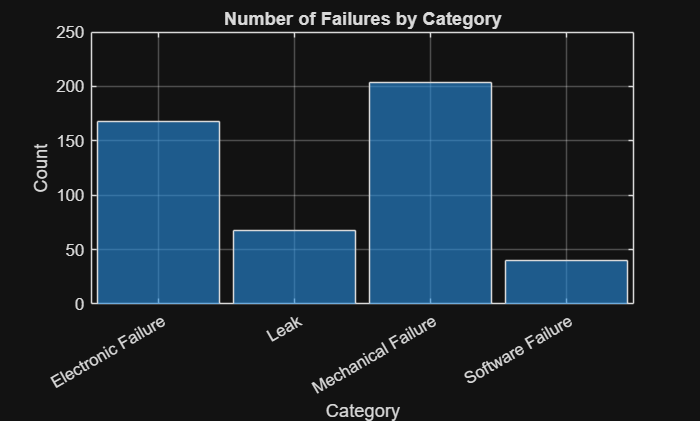


%% Failures by category
figure
histogram(reports.Category)
title("Number of Failures by Category")
xlabel("Category")
ylabel("Count")
grid on

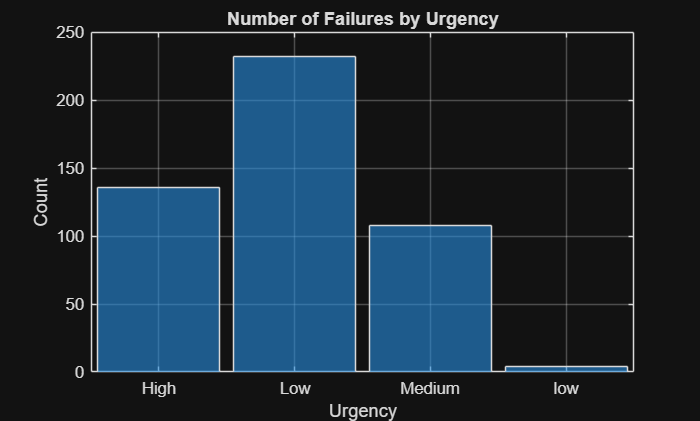


%% Failures by urgency
figure
histogram(reports.Urgency)
title("Number of Failures by Urgency")
xlabel("Urgency")
ylabel("Count")
grid on

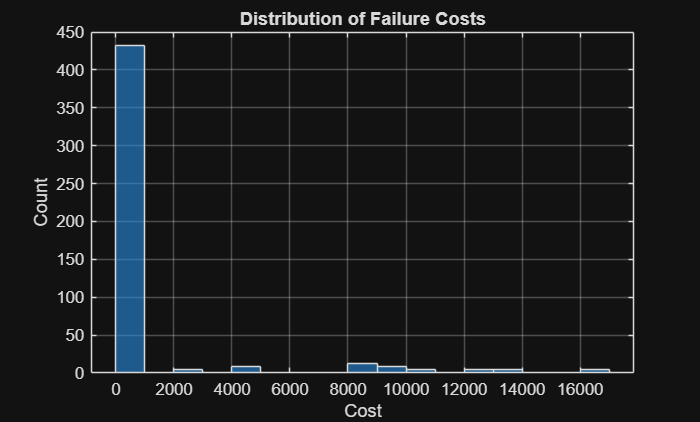


%% Distribution of costs
figure
histogram(reports.Cost)
title("Distribution of Failure Costs")
xlabel("Cost")
ylabel("Count")
grid on

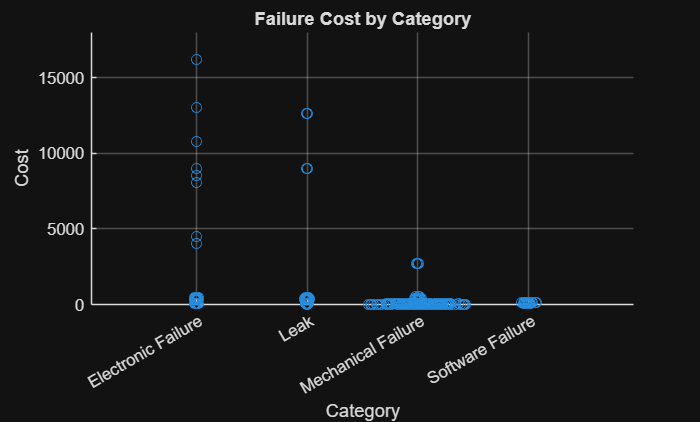

%% Task 2: Investigate the Relationship Between Category and Cost
figure
swarmchart(reports.Category, reports.Cost)
title("Failure Cost by Category")
xlabel("Category")
ylabel("Cost")
grid on


highCostReports = reports(reports.Cost > 1000, :);
groupsummary(highCostReports, "Category")

ans = 3×2 table
         Category         GroupCount
    __________________    __________

    Electronic Failure        36    
    Leak                       8    
    Mechanical Failure         4    



% Based on the swarm chart, the category with the largest number of
% high-cost failures is Electronic Failure.

% Task 3: Identify Common Description Word
rowsToKeep = reports.Category == "Electronic Failure" & reports.Cost > 1000;
rowsToKeep

rowsToKeep = 480×1 logical array
   0
   0
   1
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0



electricHiCostReports = reports(rowsToKeep, :);
electricHiCostReports = sortrows(electricHiCostReports, "Cost", "descend");
electricHiCostReports

electricHiCostReports = 36×5 table
                                Description                                      Category         Urgency       Resolution       Cost 
    ____________________________________________________________________    __________________    _______    ________________    _____

    "There are cuts to the power when starting the plant."                  Electronic Failure     High      Full Replacement    16200
    "Regular power cuts when starting plant."                               Electronic Failure     High      Full Replacement    16200
    "Power cut in factory at start up."                                     Electronic Failure     High      Full Replacement    16200
    "Occasional power cuts when beginning plant."                           Electronic Failure     High      Full Repla

% Task 4: Filter Using Terms in the Descriptions
electricHiCostReports.Description = lower(electricHiCostReports.Description);
electricHiCostReports.Description

ans = 36×1 string array
    "there are cuts to the power when starting the plant."
    "regular power cuts when starting plant."
    "power cut in factory at start up."
    "occasional power cuts when beginning plant."
    "consistent power cuts when beginning sorter plant."
    "constant power cuts when starting sorter plant."
    "startup is consistently causing a power failure the sorting plant."
    "constant power reduction when start sorting plant."
    "scanner is radiating heat then gets stuck."
    "readers is smoking at the time of start-up, emits a spark."
    "scanner gives off sparks and then smokes during startup."
    "scanner radiates heat and afterward smokes during startup."
    "mixer sparks and smokes at startup."
    "mixer smokes at time of start-up."
    "blender starts and smokes at startup."
    "sparks and smoke in the mixer at startup."
    "mixer is releasing smoke."
    "mixer is emitting smoke."
    "mixer is smoking."
    "mixer is smoking."
    "scanner 


rowsWithPower = contains(electricHiCostReports.Description, "power");
powerReports = electricHiCostReports(rowsWithPower, :);
head(powerReports)

                                Description                                      Category         Urgency       Resolution       Cost 
    ____________________________________________________________________    __________________    _______    ________________    _____

    "there are cuts to the power when starting the plant."                  Electronic Failure     High      Full Replacement    16200
    "regular power cuts when starting plant."                               Electronic Failure     High      Full Replacement    16200
    "power cut in factory at start up."                                     Electronic Failure     High      Full Replacement    16200
    "occasional power cuts when beginning plant."                           Electronic Failure     High      Full Replacement    16200
    "consistent pow

%% Task 5: Analysis and Conclusions
percentCost = sum(powerReports.Cost) / sum(reports.Cost) * 100;
percentReports = height(powerReports) / height(reports) * 100;

fprintf("Power reports account for %.2f%% of total cost.\n", percentCost)

Power reports account for 28.35% of total cost.


fprintf("Power reports account for %.2f%% of all reports.\n", percentReports)

Power reports account for 2.29% of all reports.



% Conclusion:
% Power-related electronic failures make up an important portion of the
% factory's total failure cost. Although these reports represent only part
% of all failures, they contribute significantly to the overall expense.
% This suggests that recurring power cuts and power reductions are a major
% issue for the factory.
%
% Recommendation:
% The factory should investigate the causes of power-related failures,
% especially during startup and plant operation. Preventive maintenance,
% inspection of electrical systems, and monitoring of unstable power
% conditions may help reduce these costly failures in the future.